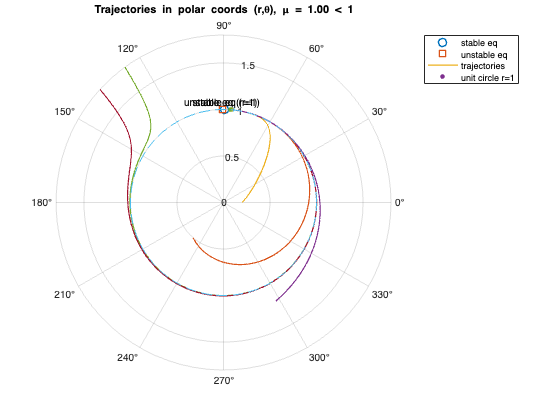

% ex4_infinite_period_bifurcation.m
% Infinite-period (SNIC-like) bifurcation in polar coordinates (r, theta)
%
% System:
%   r'     = r(1 - r^2)
%   theta' = mu - sin(theta)
% Bifurcation at mu = 1:
%   - For |mu| < 1: theta has equilibria (phase-locked); trajectories approach a fixed point on r=1.
%   - For mu > 1: theta' > 0 for all theta, giving a periodic orbit on r=1 with period
%       T(mu) = \int_0^{2pi} dtheta / (mu - sin(theta)) = 2*pi / sqrt(mu^2 - 1), mu>1.
%     As mu -> 1^+, T diverges like (mu-1)^(-1/2) (infinite-period).
%
% This script:
%   (1) Plots trajectories in POLAR coordinates using polarplot(theta, r).
%   (2) Plots the (theta,r) "cylinder-unwrapped" phase portrait with nullclines.
%   (3) Plots period vs mu for mu>1 using the closed-form expression + numerical event check.
%
% No toolboxes required.

clear; close all; clc;

%% Parameters and integration settings
mu_sub = 0.9999;      % below bifurcation: fixed points in theta
mu_sup = 1.05;      % above bifurcation: periodic rotation
mu_list_period = [1.01 1.02 1.05 1.10 1.30]; % for period demonstration

tmax_sub = 25;      % sufficient for convergence to equilibrium
tmax_sup = 2*50;    % enough to see a couple of rotations for mu_sup (adjust if desired)

opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

%% (A) Polar trajectories for mu < 1 (phase-locked equilibrium on r=1)
figure('Name','Infinite-period bifurcation: mu < 1 (polar trajectories)');
pax = polaraxes; hold(pax,'on'); pax.ThetaZeroLocation = 'right';
title(pax, sprintf('Trajectories in polar coords (r,\\theta), \\mu = %.2f < 1', mu_sub));

% Stable/unstable theta fixed points on r=1
theta_stable = asin(mu_sub);                  % stable (cos>0)
theta_unstable = pi - asin(mu_sub);           % unstable (cos<0)

% Mark equilibria on r=1
polarplot(pax, theta_stable, 1, 'o', 'MarkerSize', 8, 'LineWidth', 1.5);
text(pax, theta_stable, 1.08, 'stable eq (r=1)', 'HorizontalAlignment','center');
polarplot(pax, theta_unstable, 1, 's', 'MarkerSize', 8, 'LineWidth', 1.5);
text(pax, theta_unstable, 1.08, 'unstable eq (r=1)', 'HorizontalAlignment','center');

% Simulate a few initial conditions
ICs = [ ...
    0.2,  0.0;
    1.8,  2.2;
    1.8,  2.4;
    0.5,  4.0;
    1.2,  5.2];
for k = 1:size(ICs,1)
    r0 = ICs(k,1); th0 = ICs(k,2);
    [t,z] = ode45(@(t,z) polarODE(t,z,mu_sub), [0 tmax_sub], [r0; th0], opts);
    polarplot(pax, wrapTo2Pi(z(:,2)), z(:,1), 'LineWidth', 1.2);
    polarplot(pax, wrapTo2Pi(z(end,2)), z(end,1), '.', 'MarkerSize', 14);
end
% Show the unit circle (stable r-nullcline)
th = linspace(0,2*pi,400);
polarplot(pax, th, ones(size(th)), '--', 'LineWidth', 1.0);
legend(pax, {'stable eq','unstable eq','trajectories','unit circle r=1'}, 'Location','bestoutside');

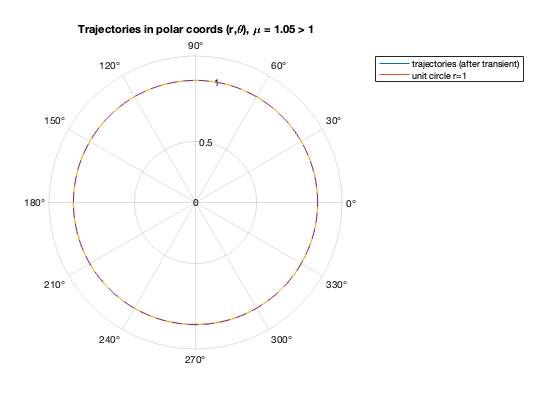


% [Insert figure on slides: Polar trajectories for mu<1 showing convergence to (r=1, theta=asin(mu)).]

%% (B) Polar trajectories for mu > 1 (periodic rotation on r=1)
figure('Name','Infinite-period bifurcation: mu > 1 (polar trajectories)');
pax = polaraxes; hold(pax,'on'); pax.ThetaZeroLocation = 'right';
title(pax, sprintf('Trajectories in polar coords (r,\\theta), \\mu = %.2f > 1', mu_sup));

ICs = [ ...
    0.2,  0.0;
    1.6,  1.0;
    0.8,  4.5];
for k = 1:size(ICs,1)
    r0 = ICs(k,1); th0 = ICs(k,2);
    [t,z] = ode45(@(t,z) polarODE(t,z,mu_sup), [0 tmax_sup], [r0; th0], opts);
    % To avoid visual clutter, plot only the last ~one rotation (after transient in r)
    idx = find(t > 10, 1, 'first'); % transient cutoff
    if isempty(idx), idx = 1; end
    polarplot(pax, wrapTo2Pi(z(idx:end,2)), z(idx:end,1), 'LineWidth', 1.2);
end
% Unit circle (attractor for r)
polarplot(pax, th, ones(size(th)), '--', 'LineWidth', 1.0);
legend(pax, {'trajectories (after transient)','unit circle r=1'}, 'Location','bestoutside');

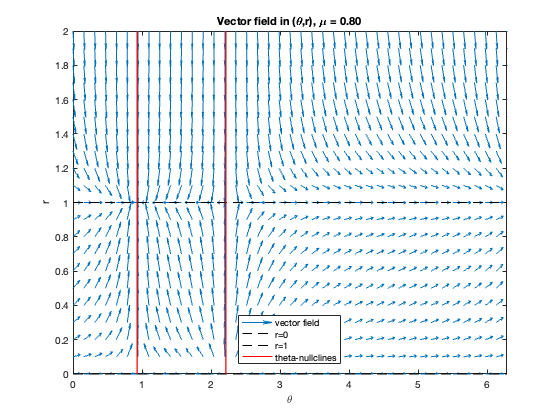


% [Insert figure on slides: Polar trajectories for mu>1 illustrating rotation and approach to r=1.]

%% (C) Unwrapped phase portrait in (theta, r) with nullclines (choose a representative mu)
mu_for_field = 0.80; % change to mu_sup to see the "no-theta-nullcline" case

theta_grid = linspace(0,2*pi,41);
r_grid = linspace(0,2,21);
[TH,RR] = meshgrid(theta_grid, r_grid);
dR = RR.*(1 - RR.^2);
dTH = mu_for_field - sin(TH);

% Normalize for quiver readability
speed = sqrt(dR.^2 + dTH.^2) + 1e-12;
dR_n = dR ./ speed;
dTH_n = dTH ./ speed;

figure('Name','(theta,r) phase portrait (unwrapped)');
quiver(TH, RR, dTH_n, dR_n, 0.6, 'LineWidth', 0.8); hold on;
xlabel('\theta'); ylabel('r');
title(sprintf('Vector field in (\\theta,r), \\mu = %.2f', mu_for_field));
xlim([0 2*pi]); ylim([0 2]);

% Nullclines:
% r-nullclines: r=0 and r=1 (for r>=0)
plot([0 2*pi], [0 0], 'k--', 'LineWidth', 1.2);
plot([0 2*pi], [1 1], 'k--', 'LineWidth', 1.2);

% theta-nullcline (exists only if |mu|<=1): mu - sin(theta) = 0 => sin(theta)=mu
if abs(mu_for_field) <= 1
    th1 = asin(mu_for_field);
    th2 = pi - asin(mu_for_field);
    plot([th1 th1], [0 2], 'r-', 'LineWidth', 1.2);
    plot([th2 th2], [0 2], 'r-', 'LineWidth', 1.2);
    legend({'vector field','r=0','r=1','theta-nullclines'}, 'Location','best');
else
    legend({'vector field','r=0','r=1'}, 'Location','best');
end

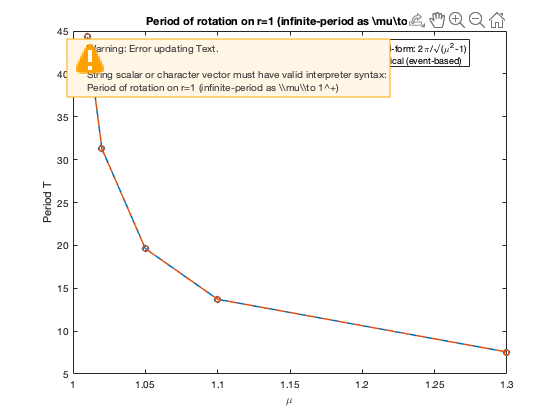


% [Insert figure on slides: Unwrapped (theta,r) field + nullclines to explain fixed point vs. rotation.]

%% (D) Period vs mu for mu>1: closed-form and numerical event check
T_closed = 2*pi ./ sqrt(mu_list_period.^2 - 1);

% Numerical check via event when theta reaches 2*pi starting from (r,theta)=(1,0)
T_num = nan(size(mu_list_period));
for k = 1:numel(mu_list_period)
    mu = mu_list_period(k);
    opts_ev = odeset(opts, 'Events', @(t,z) eventTheta2Pi(t,z));
    [t,z,te,ze,ie] = ode45(@(t,z) polarODE(t,z,mu), [0 500], [1; 0], opts_ev); %#ok<ASGLU>
    if ~isempty(te)
        T_num(k) = te(end);
    end
end

figure('Name','Period vs mu (mu>1)');
plot(mu_list_period, T_closed, 'o-', 'LineWidth', 1.5); hold on;
plot(mu_list_period, T_num, 's--', 'LineWidth', 1.5);
xlabel('\mu'); ylabel('Period T');
title('Period of rotation on r=1 (infinite-period as \mu\to 1^+)');
legend({'Closed-form: 2\pi/\surd(\mu^2-1)','Numerical (event-based)'}, 'Location','best');

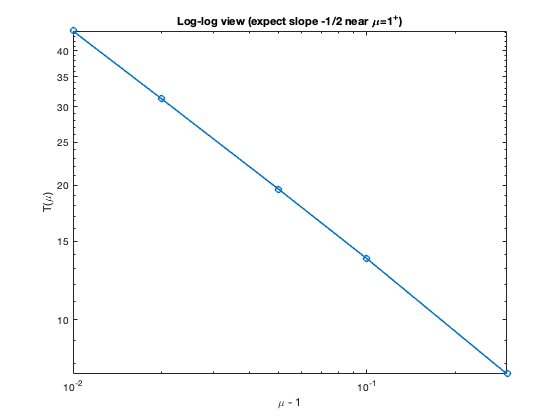


% Optional: show scaling vs (mu-1)
figure('Name','Scaling of period near mu=1');
delta = mu_list_period - 1;
loglog(delta, T_closed, 'o-', 'LineWidth', 1.5);
xlabel('\mu - 1'); ylabel('T(\mu)');
title('Log-log view (expect slope -1/2 near \mu=1^+)');


%% ---------------- Local functions ----------------

function dz = polarODE(~, z, mu)
    r = z(1);
    th = z(2);
    dr = r*(1 - r^2);
    dth = mu - sin(th);
    dz = [dr; dth];
end

function [value, isterminal, direction] = eventTheta2Pi(~, z)
    % Stop when theta reaches 2*pi (monotone for mu>1)
    value = z(2) - 2*pi;
    isterminal = 1;
    direction = +1;
end

function th = wrapTo2Pi(th)
    % Wrap angles to [0,2*pi) without requiring Mapping Toolbox
    th = mod(th, 2*pi);
end
